# General Linear Modelling

Last week we talked about linear regression, in which we modeled continuous data. But what happens when data is binary, categorical or count? 

## *Binary data*

[Binary data](https://en.wikipedia.org/wiki/Binary_data) only takes two possible states, traditionally termed 0 and +1 in accordance with the binary numeral system and Boolean algebra. In addition, *binary variables* only take two values, such as Male or Female, True or False and Yes or No.

We will start by generating simulated binary data and try to fit this with a **linear **and **quadratic model.**

*Example I: Perceptual choise experiment - random dots of varying coherence levels move to the left or right.*

% motion coherence of stimulus 
stim1 = -5:0.01:5;

% create a function for generating binary data (simBinary) 
beta = 2; 

Beta is the regression coefficients: it measures how strongly each predictor variable influences the dependent variable. The beta is measured in units of standard deviation.

y = simBinary(stim1, beta);

% plot the binary data
plot(stim1,y,'.') 
hold on

Next, we try to fit a [linear model](https://en.wikipedia.org/wiki/Linear_model)

STATS = regstats(y,stim1,'linear') % regstats is used for regression diagnostics for linear models. 

STATS =         source: 'regstats'
             Q: [1001×2 double]
             R: [2×2 double]
          beta: [2×1 double]
          covb: [2×2 double]
          yhat: [1001×1 double]
             r: [1001×1 double]
           mse: 0.0761
       rsquare: 0.6961
    adjrsquare: 0.6958
      leverage: [1001×1 double]
        hatmat: [1001×1001 double]
          s2_i: [1001×1 double]
        beta_i: [2×1001 double]
      standres: [1001×1 double]
       studres: [1001×1 double]
       dfbetas: [2×1001 double]
         dffit: [1001×1 double]
        dffits: [1001×1 double]
      covratio: [1001×1 double]
         cookd: [1001×1 double]
         tstat: [1×1 struct]
         fstat: [1×1 struct]
        dwstat: [1×1 struct]


% plot fitted model 
plot(stim1,STATS.yhat)


Here, we fit a [quadratic term](http://www.classzone.com/eservices/home/pdf/teacher/LA205HAD.pdf) and plot the result

STATS = regstats(y,stim1,'quadratic'); 
plot(stim1, STATS.yhat)

 Why do you think is the linear model not right for this data type? 

## General linear model 

The [general linear model ](https://en.wikipedia.org/wiki/General_linear_model)(GLM) is a linear model and determines whether the means of two or more groups differ. You can include random factors, covariates, or a mix of crossed and nested factors. In addition, you can use **stepwise regression** to help determine the model. The GLM can be written as                         


$$Y = XB + U$$


where *Y* is a matrix with series of multivariate measurements, *X* is a matrix that might be a design matrix, *B* is a matrix containing parameters that are usually to be estimated and *U* is a matrix containing errors or noise. The errors are usually assumed to be uncorrelated across measurements, and follow a *multivariate normal distribution*. If the errors do not follow a multivariate normal distribution, *generalized linear models* may be used to relax assumptions about *Y* and *U*.

There are ways to "linearize" a non-linear problem. For example, using [logistic regression](https://en.wikipedia.org/wiki/Logistic_regression), or **logit regression**, with a maximum likelihood fit to model the probability for each outcome, rather than a numerical outcome. In the following we will use ‘glmfit’, ‘glmval’,‘fitglm’ for logistic regression. The glmfit has the structure B = glmfit(X,Y,DISTR) and fits a generalized linear model using the predictor matrix X, response Y, and distribution DISTR.

We will specify either the **logit** function or **probit** function in these fits. 

- The [logit](https://en.wikipedia.org/wiki/Logit) is a regression model where the dependent variable (DV) is categorical and the logit function is the inverse of the sigmoidal "logistic" function. When the function's parameter represents a probability *p*, the logit function gives the *log-odds,* or the logarithm of the odds *p*/(1 − *p*). 

- The [probit ](https://en.wikipedia.org/wiki/Probit)function is a regression model where the DV can only take two values, e.g. Bicycle or No Bicycle. The probit is a quantile function associated with the standard normal distribution, which is commonly denoted as N(0,1). Mathematically, it is the inverse of the *cumulative distribution function* of the standard normal 

- distribution, which is denoted as  $\Phi(z)$, so the probit is denoted as $\Phi^{-1}(p)$.

We start with glmfit tha

- t fit a GLM with a **logit**

[b,dev,stats] = glmfit(stim1,y','binomial'); %logit is the default link for binomial


NB, for a vector, such as response values y, the apostrophe in y' means that the column is changed into a vector row. If y was a matrix,y' means that we use the transpose of the matrix. 


% We can use the coefficients to predict the data 
phat1 = 1./(1+exp(-(b(1)+stim1*b(2)))); 
plot(stim1,phat1)

% Or use glmval function to do that 
phat2 = glmval(b, stim1, 'logit'); % glmval predict values for a generalized linear model
plot(stim1,phat2)

mdl = 
Generalized linear regression model:
    logit(y) ~ 1 + x1
    Distribution = Binomial

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    0.028418    0.13766    0.20644       0.83645
    x1               1.8942     0.1441     13.145    1.8233e-39


1001 observations, 999 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 1.04e+03, p-value = 2.83e-228

ans =     0.0284
    1.8942


Matlab's fitglm fits the model specified after the dataset. In the first case, we use linear main effect terms only.

mdl = fitglm(stim1,y','linear','Distribution','binomial','link','logit') 

ans = 0.0284

mdl.Coefficients.Estimate % this gives you the coefficients of mdl

ans =                    Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    0.028418    0.13766    0.20644       0.83645
    x1               1.8942     0.1441     13.145    1.8233e-39


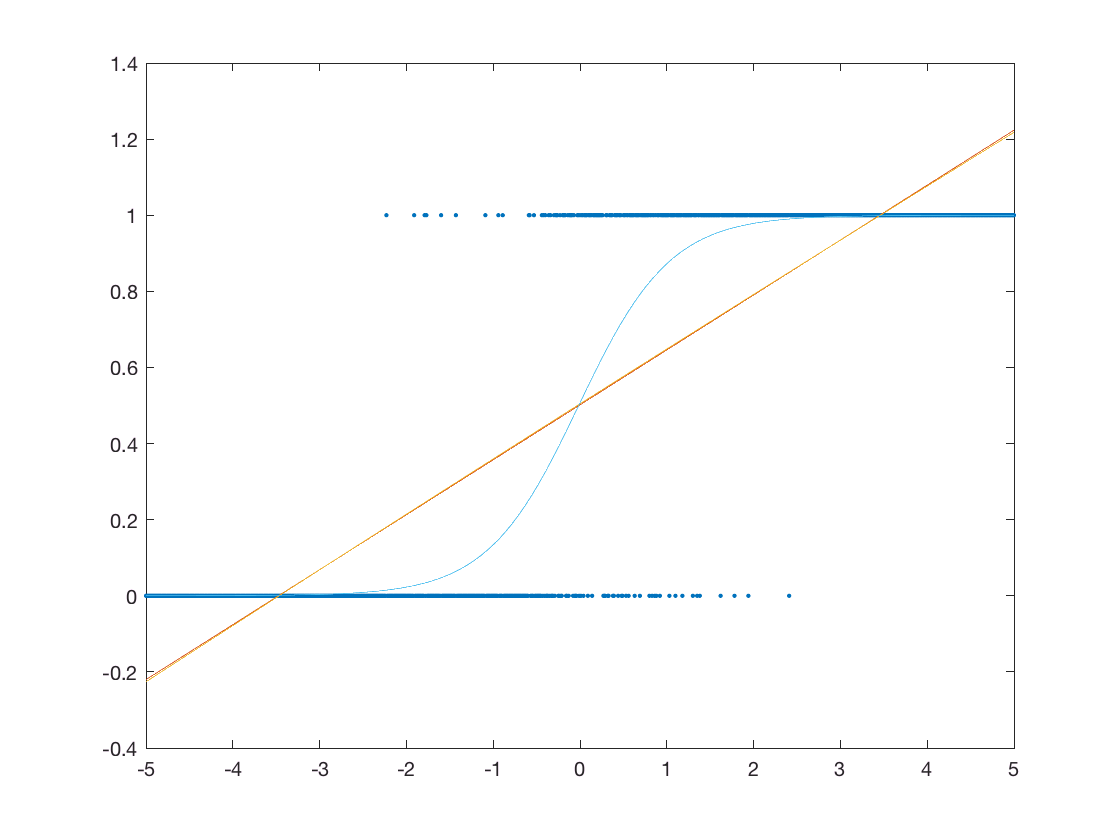

mdl.Coefficients.Estimate(1) % gives you only the first coefficient
mdl.Coefficients 
mdl.Diagnostics; % remove semicolumn to see output

You can use methods with the object to make predictions 

phat3 = predict(mdl,stim1'); 
plot(stim1,phat3)

mdl = 
Generalized linear regression model:
    probit(y) ~ 1 + x1
    Distribution = Binomial

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)    0.0056648    0.075085    0.075444       0.93986
    x1                1.0184    0.069179      14.721    4.7336e-49


1001 observations, 999 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 1.04e+03, p-value = 9.56e-228

Instead of logit you can use a **probit**. In practice it doesn't make much difference. However, in principle the difference beteen the two is mainly in the link function. The [link function](https://en.wikipedia.org/wiki/Generalized_linear_model#Link_function) provides the relationship between the linear predictor and the mean of the distribution function. 

In Logit: 


$$Pr(Y=1|X) = [1 + exp^{-X' \beta}]^{-1}$$


In Probit (cumulative normal pdf): 


$$Pr(Y = 1|X) = \Phi(X' \beta)$$


Therefore, the logit has slightly flatter tails, i.e probit curve approaches the axes more quickly than the  curve. 

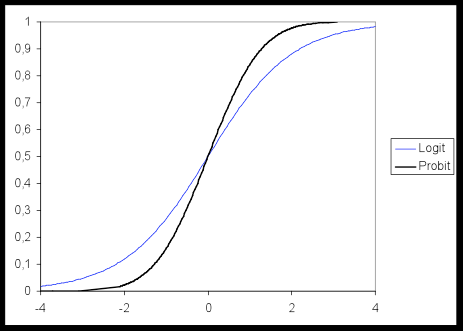

Also, the difference is that the probit uses a non-linear function, i.e. the normal cumulative distribution function, rather than the logistic one in the logit.

mdl = fitglm(stim1,y','linear','Distribution','binomial','link','probit') 

fitglm and glmfit are similar with some differences :

- fitglm provides more flexibility and returns an object. 

- linear is the default, can add quadratic or interaction terms  

- logit is the default for binomial distribution 

- check out the doc page (help fitglm or glmfit) on GeneralizedLinearModel class 

## Binary data with multiple predictors

Here we will fit binary data with multiple predictors using logistic regression.

*Example II: We will look at a slightly more complicated situation with more predictors and fit alogistic regression *

stim1 = -5:0.1:5; % Generate binary data (the same stimulus as before).

But there is also another stimulus that appears either on the left pr on the right, and may bias performance 

bias = zeros(size(stim1)); 
bias(1:2:length(bias)) = 1;

% Generate the input matrix 
stim = [stim1' bias']; 

mdl = 
Generalized linear regression model:
    logit(y) ~ 1 + x1 + x2
    Distribution = Binomial

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   ___________    _______    ___________    __________

    (Intercept)    -5.4434e-16    0.57002    -9.5495e-16             1
    x1                  1.6236    0.38088         4.2628    2.0184e-05
    x2                  4.7369     1.3514         3.5053    0.00045617


101 observations, 98 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 92.1, p-value = 1.02e-20

beta = [2;5]; 
[y, prob] =simBinary(stim, beta);

% Fit logistic model 
mdl = fitglm(stim,y','Distribution','binomial')

mdl = 
Generalized linear regression model:
    logit(y) ~ 1 + x1 + x2 + x3
    Distribution = Binomial

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     1.0184     0.93168     1.0931       0.27433
    x1              1.8377     0.45982     3.9965    6.4282e-05
    x2              5.4931        1.61      3.412     0.0006449
    x3             -2.1324      1.5478    -1.3777        0.1683


101 observations, 97 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 94.1, p-value = 2.82e-20

Look at the coefficients: are they significant? As you can see, beta has now two coefficients: one for each predictor.

Now, lets fit a logistic model with a third unrelated predictor. Suppose that this predictor doesn't really explain much.

addPred = rand(size(stim1)); 
predictors = [stim addPred']; 
mdl = fitglm(predictors,y','Distribution','binomial')

How do the coefficients look now? 

## *Count data*

[Count data](https://en.wikipedia.org/wiki/Count_data) is a type of data in which the observations can take only the non-negative integer values {0, 1, 2, 3, ...}, and where these integers arise from counting rather than ranking. An example of count data is the firing rate. 

*Example III: Here we generate count data based on the *[*Poisson distribution *](https://en.wikipedia.org/wiki/Poisson_distribution)

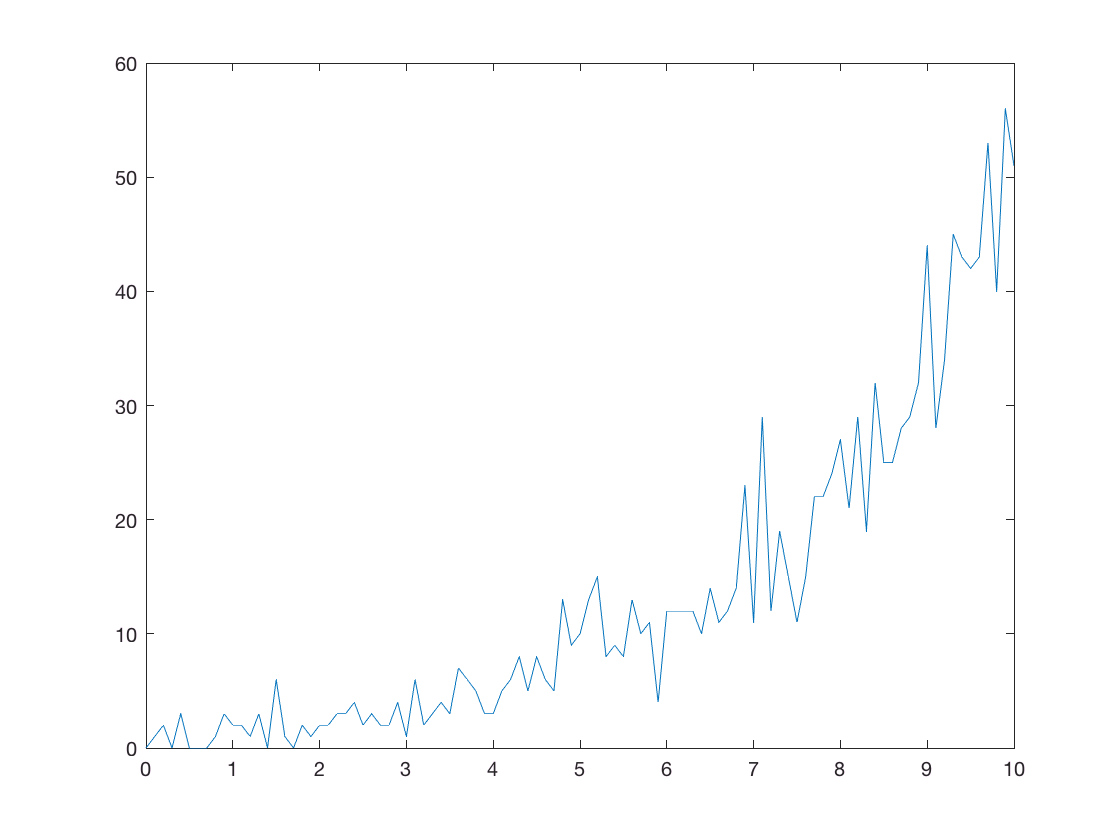

stim1 = 0:0.1:10; 
beta = 0.4; 

lambda = exp(stim1*beta); % lambda is the Poisson parameter
y = poissrnd(lambda);

mdl = 
Generalized linear regression model:
    log(y) ~ 1 + x1
    Distribution = Poisson

Estimated Coefficients:
                   Estimate      SE        tStat       pValue   
                   ________    _______    _______    ___________

    (Intercept)    0.089063    0.10219    0.87157        0.38344
    x1              0.38399    0.01285     29.882    3.3602e-196


101 observations, 99 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 1.21e+03, p-value = 2.07e-265


figure 
plot(stim1,y)

[Poisson regression](https://en.wikipedia.org/wiki/Poisson_regression) is a GLM form of regression analysis used to model count data and contigency tables. Poisson regression assumes the response variable *Y* has a Poisson distribution, and assumes the logarithm of its expected value can be modeled by a linear combination of unknown parameters. A Poisson regression model is sometimes known as a *log-linear model*, especially when used to model contingency tables. The default link function for Poisson distribution is log 

mdl = fitglm(stim1,y','Distribution','poisson') % fit the Poisson regression
% Generate more complex dataset 
stim1 = 0:0.1:10; 
bias=zeros(size(stim1)); 
bias(1:2:length(bias))=1;
addNoise = rand(size(stim1));

stim = [stim1' bias' addNoise']; 
beta = [0.1;0.5; 0.2]; 
lambda = stim*beta; 

mdl = 
Generalized linear regression model:
    log(y) ~ 1 + x1 + x2
    Distribution = Poisson

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    0.080938     0.16484    0.49101       0.62342
    x1              0.10324    0.022068     4.6783    2.8925e-06
    x2              0.49286     0.12974     3.7989    0.00014535


101 observations, 98 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 37.5, p-value = 7.23e-09

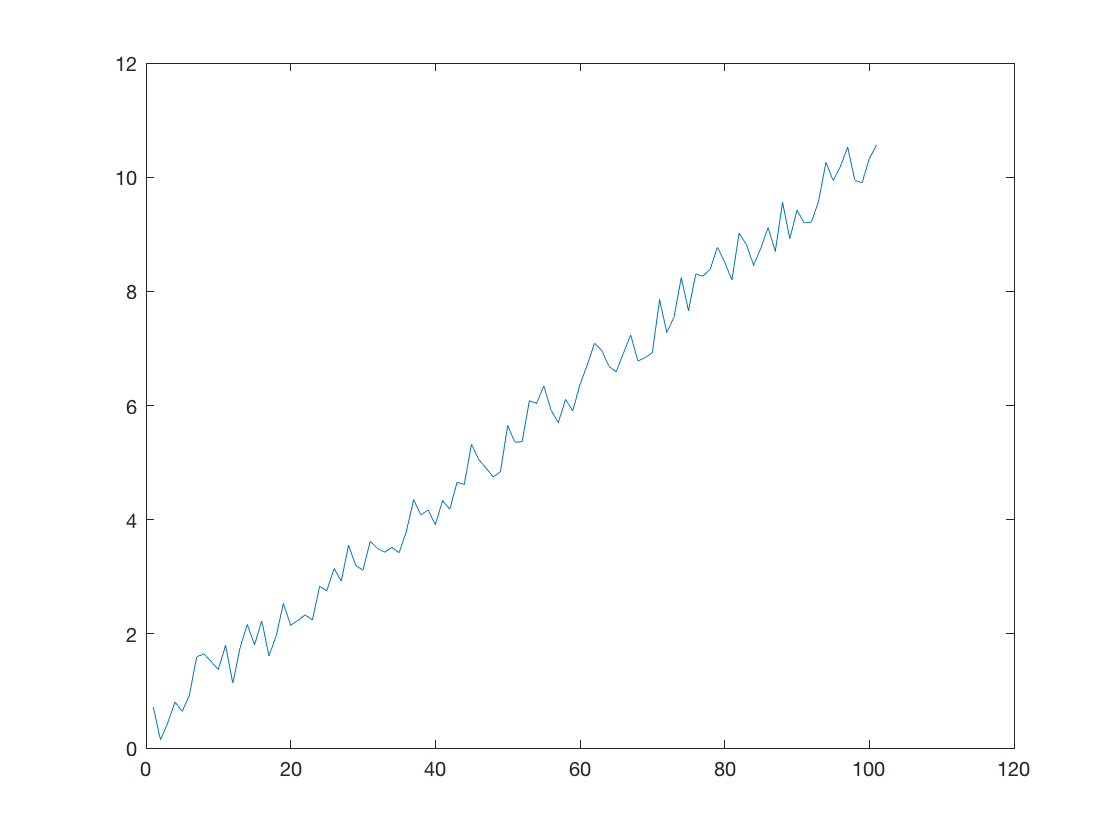

mdl = 
Generalized linear regression model:
    log(y) ~ 1 + x1 + x2 + x3
    Distribution = Poisson

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   _________    _______    _________    _________

    (Intercept)      0.08792    0.19089      0.46058       0.6451
    x1               0.11889    0.21727      0.54721      0.58423
    x2               0.49236    0.12992       3.7897    0.0001508
    x3             -0.015583    0.21521    -0.072405      0.94228


101 observations, 97 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 37.5, p-value = 3.62e-08

y = exp(lambda);

% Poisson regression 
predictors = [stim1' bias']; 
mdl = fitglm(predictors,y','Distribution','poisson')

## Collinearity

[Multicollinearity](https://en.wikipedia.org/wiki/Multicollinearity) (also *collinearity*) is a phenomenon in which two or more predictor variables in a multiple regression model are highly correlated, meaning that one can be linearly predicted from the others with a substantial degree of accuracy. In this situation the coefficient estimates of the multiple regression may change erratically in response to small changes in the model or the data. 

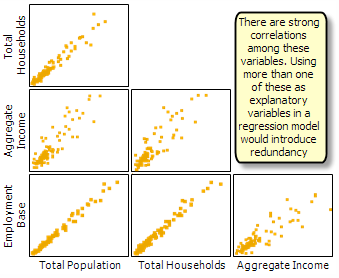

*Example IV: Here we look for collinearity between predictors. This will be performed by including the fatigue predictor: what if subjects are more tired at the second half of the experment? Maybe we should take this into account!*

% Generate fatigue predictor 
fatigue = [0:0.1:10] + rand(size(stim1)); 
plot(fatigue)
predictors = [predictors fatigue']; 

ans =     1.0000    0.9951
    0.9951    1.0000


mdl = fitglm(predictors,y','Distribution','poisson') 

Compare the coefficients to what we had before - what changed?

Collinearity in a model can be problematic. As we see here, fatigue is strongly correlated with stim1, which affects your results. 

corrcoef(fatigue, stim1)

1. Removing x3, Deviance = 0.82026, Chi2Stat = 0.0052446, PValue = 0.94227


mdl = 
Generalized linear regression model:
    log(y) ~ 1 + x1 + x2
    Distribution = Poisson

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    0.080938     0.16484    0.49101       0.62342
    x1              0.10324    0.022068     4.6783    2.8925e-06
    x2              0.49286     0.12974     3.7989    0.00014535


101 observations, 98 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 37.5, p-value = 7.23e-09

ans =     1.0000    0.9951
    0.9951    1.0000


1. Adding x1, Deviance = 15.7187, Chi2Stat = 22.5915, PValue = 2.00371e-06
2. Adding x2, Deviance = 0.82026, Chi2Stat = 14.8984, PValue = 0.000113459


mdl = 
Generalized linear regression model:
    log(y) ~ 1 + x1 + x2
    Distribution = Poisson

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    0.080938     0.16484    0.49101       0.62342
    x1              0.10324    0.022068     4.6783    2.8925e-06
    x2              0.49286     0.12974     3.7989    0.00014535


101 observations, 98 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 37.5, p-value = 7.23e-09

## Stepwise regression

To decide whether or not to include predictors in your model you can use a "stepwise" regression. [Stepwise regression](https://en.wikipedia.org/wiki/Stepwise_regression) is a method of fitting regression models in which the choice of predictive variables is carried out by an automatic procedure. In each step, a variable is considered for addition to or subtraction from the set of explanatory variables based on some prespecified criterion. Usually, this takes the form of a sequence of F-test or t-tests[](https://en.wikipedia.org/wiki/T-test), but other techniques are possible, such as [adjusted *R*2](https://en.wikipedia.org/wiki/Adjusted_R-squared), [Akaike information criterion](https://en.wikipedia.org/wiki/Akaike_information_criterion), [Bayesian information criterion](https://en.wikipedia.org/wiki/Bayesian_information_criterion), [Mallows's *C**p*](https://en.wikipedia.org/wiki/Mallows%27s_Cp), [PRESS](https://en.wikipedia.org/wiki/PRESS_statistic), or [false discovery rate](https://en.wikipedia.org/wiki/False_discovery_rate). You can start with a minimal model and add predictors; or start from some model and either add or remove predictors.

% Start with a full model 
mdl = stepwiseglm(predictors,y','linear','Distribution','poisson')
corrcoef(fatigue, stim1) % so you see that fatigue is highly correlated with stim1.
% Start with a constant 
mdl = stepwiseglm(predictors,y','constant','Distribution','poisson')

In stepwise regression, finding the best set of regressors is highly debated, but also the fun of the game.